rootfolder = '../../exp/tartanair_full_semantic/';
use_icp = true

use_icp = logical
   1


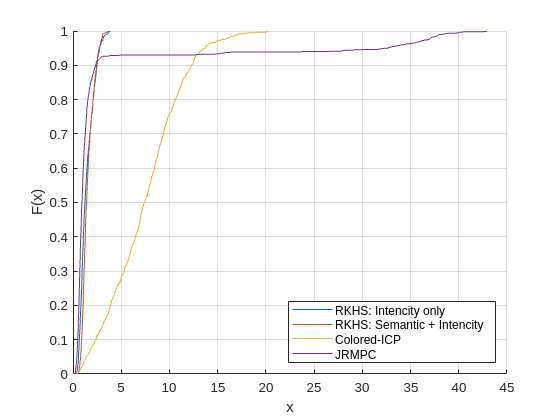

gtfilename_cvo = append(rootfolder,'cvo_error_list.txt');
error_cvo = readmatrix(gtfilename_cvo);
gtfilename_cvosem = append(rootfolder,'cvosem_error_list.txt');
error_cvosem = readmatrix(gtfilename_cvosem);
gtfilename_jrmpc = append(rootfolder,'jrmpc_error_list.txt');
error_jrmpc = readmatrix(gtfilename_jrmpc);
if use_icp==true
    gtfilename_icp = append(rootfolder,'icp_error_list.txt');
    error_icp = readmatrix(gtfilename_icp);
end
title_string = "total tartanair";
hold on

cdfplot(error_cvo)


if use_icp==true
    cdfplot(error_cvosem)
    cdfplot(error_icp)
    cdfplot(error_jrmpc)
    legend(["RKHS: Intencity only","RKHS: Semantic + Intencity","Colored-ICP","JRMPC"],'Location','southeast')
else
    cdfplot(error_jrmpc)
    legend(["RKHS","JRMPC"],'NumColumns',2,'Location','southwest')
end
title("")
% title(title_string)
hold off


%% 

cla
rootfolder = '../../exp/';
use_icp = false

use_icp = logical
   0


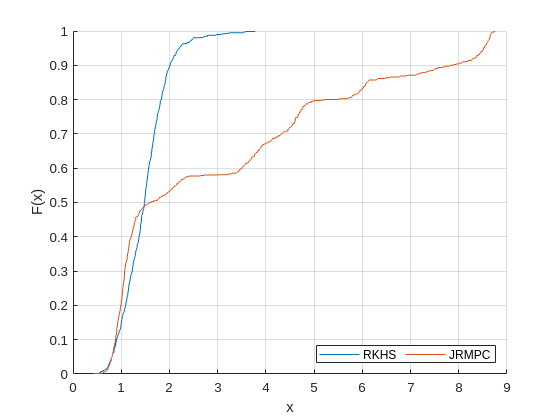

gtfilename_cvo = append(rootfolder,'cvo_error_list.txt');
error_cvo = readmatrix(gtfilename_cvo);
gtfilename_cvosem = append(rootfolder,'cvosem_error_list.txt');
error_cvosem = readmatrix(gtfilename_cvosem);
gtfilename_jrmpc = append(rootfolder,'jrmpc_error_list.txt');
error_jrmpc = readmatrix(gtfilename_jrmpc);
if use_icp==true
    gtfilename_icp = append(rootfolder,'icp_error_list.txt');
    error_icp = readmatrix(gtfilename_icp);
end
title_string = "total tartanair";
hold on

cdfplot(error_cvo)


if use_icp==true
    cdfplot(error_cvosem)
    cdfplot(error_icp)
    cdfplot(error_jrmpc)
    legend(["RKHS: Intencity only","RKHS: Semantic + Intencity","Colored-ICP","JRMPC"],'Location','southeast')
else
    cdfplot(error_jrmpc)
    legend(["RKHS","JRMPC"],'NumColumns',2,'Location','southeast')
end
title("")
% title(title_string)
hold off


%% 

## 0.5

cla
rootfolder = '../../exp/tartanair_full_semantic/';
gtfilename_cvo = append(rootfolder,'cvo_error_list0.5.txt');
error_cvo = readmatrix(gtfilename_cvo)

error_cvo =     2.5035
    1.8417
    2.2082
    2.1965
    1.4877
    1.9237
    2.7682
    2.7324
    2.9940
    2.5985


gtfilename_jrmpc = append(rootfolder,'jrmpc_error_list0.5.txt');
error_jrmpc = readmatrix(gtfilename_jrmpc)

error_jrmpc =     1.5583
    1.3715
   38.3364
    1.2642
   34.9594
    2.1585
    1.3390
    2.4643
    1.3077
    1.8711


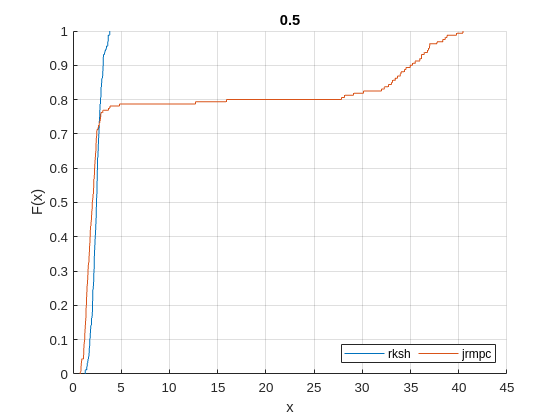

hold on
cdfplot(error_cvo)
cdfplot(error_jrmpc)
legend(["rksh","jrmpc"],'Location','southeast')
title("0.5")
hold off

## 0.0

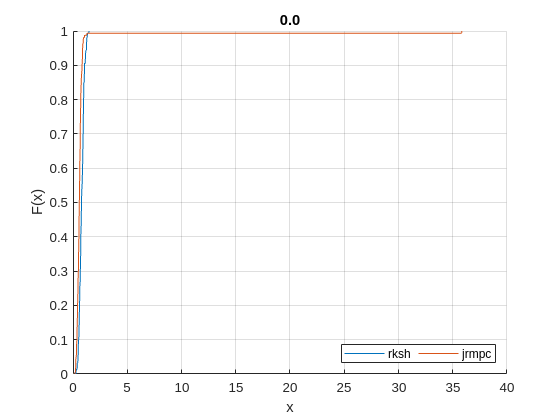

cla
rootfolder = '../../exp/tartanair_full_semantic/';
gtfilename_cvo = append(rootfolder,'cvo_error_list0.0.txt');
error_cvo = readmatrix(gtfilename_cvo);
gtfilename_jrmpc = append(rootfolder,'jrmpc_error_list0.0.txt');
error_jrmpc = readmatrix(gtfilename_jrmpc);
hold on
cdfplot(error_cvo)
cdfplot(error_jrmpc)
legend(["rksh","jrmpc"])
title("0.0")
hold off

## 0.125

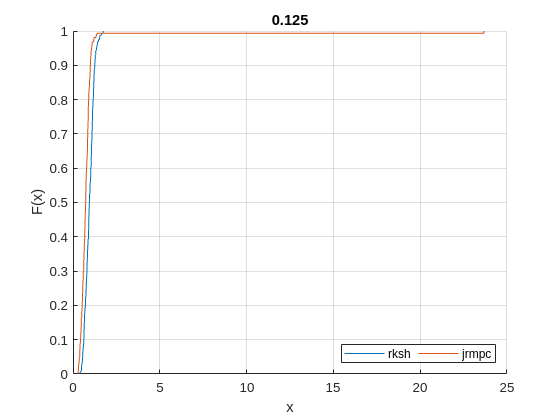

cla
rootfolder = '../../exp/tartanair_full_semantic/';
gtfilename_cvo = append(rootfolder,'cvo_error_list0.125.txt');
error_cvo = readmatrix(gtfilename_cvo);
gtfilename_jrmpc = append(rootfolder,'jrmpc_error_list0.125.txt');
error_jrmpc = readmatrix(gtfilename_jrmpc);
hold on
cdfplot(error_cvo)
cdfplot(error_jrmpc)
title("0.125")
legend(["rksh","jrmpc"])
hold off